# Draw Saturn Rocket

The `DrawSaturn(opts)` function is used throughout [ManOnTheMoon.mlx](matlab:open('../ManOnTheMoon.mlx')) to plot the Saturn V rocket and all the details coming from the question in this script.

**Input Arguments:**

- `ControlVolume (integer)`

- `DrawFootball (logical) `

- `Highlight (string)`

- `NormalVector (logical)`

- `Gravity (logical)`

- `ZoomIn (logical)`

- `DrawExhaustVelocity (logical)`

- `DrawExhaustMassFlow (logical)`

- `WriteExhaustVelocity (logical)`

- `WriteExhaustMassFlow (logical)`

- `WriteMass (logical)`

- `DrawThrust (logical)`

- `DrawAcceleration (logical)`

- `PathAngle (scalar)`

- `WriteEquation (string)`

**Example:**

`DrawSaturn(ZoomIn=true, DrawExhaustVelocity=true, WriteExhaustVelocity=true)`

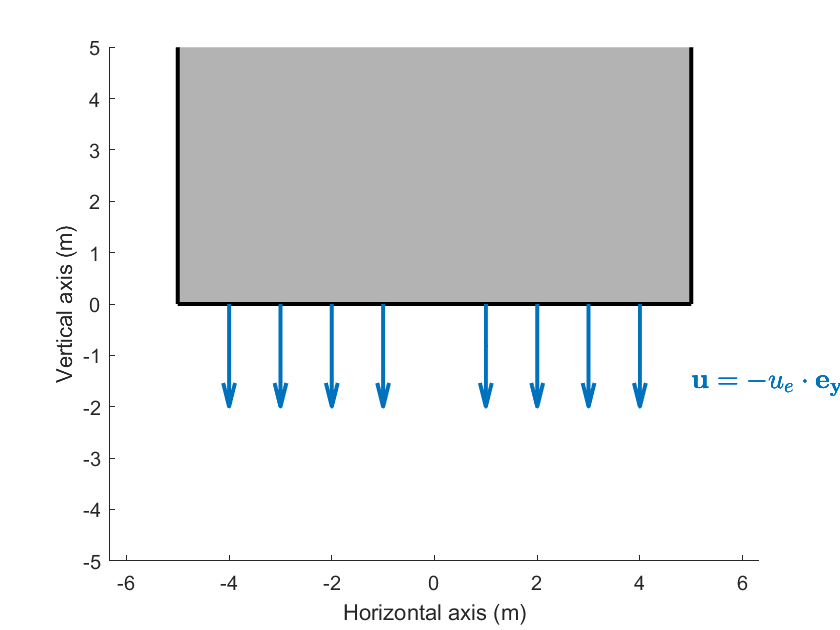

function ax = DrawSaturn(opts)
    arguments
        opts.ControlVolume (1,1) uint8 {mustBeMember(opts.ControlVolume, [0 1 2 3])} = 0 
        opts.DrawFootball (1,1) logical = false
        opts.Highlight (1,1) string {mustBeMember(opts.Highlight, ["none" "CV" "CSR" "CSL" "CSB"])} = "none"
        opts.NormalVector (1,1) logical = false
        opts.Gravity (1,1) logical = false
        opts.ZoomIn (1,1) logical = false
        opts.DrawExhaustVelocity (1,1) logical = false
        opts.DrawExhaustMassFlow (1,1) logical = false
        opts.WriteExhaustVelocity (1,1) logical = false
        opts.WriteExhaustMassFlow (1,1) logical = false
        opts.WriteMass (1,1) logical = false
        opts.DrawThrust (1,1) logical = false
        opts.DrawAcceleration (1,1) logical = false
        opts.PathAngle (1,1) double = 0 % (degree)
        opts.WriteEquation (1,1) string = ""
    end

    % Define the axis:
    f = figure;
    ax = axes(f);
    xlabel(ax,"Horizontal axis (m)")
    ylabel(ax,"Vertical axis (m)")
    axis equal
    ColorHighlight = ax.ColorOrder(3,:);

    % Plot Control Volume background for config A and C:
    if opts.ControlVolume == 1 || opts.ControlVolume == 3
        CV = patch([-40 40 40 -40],[0 0 120 120],ax.ColorOrder(1,:),FaceAlpha=0.2, ...
            LineStyle="none",DisplayName='Control Volume');
        CV.Annotation.LegendInformation.IconDisplayStyle = 'off';
        CS = line([-40  40],[120 120],Color=ax.ColorOrder(1,:),LineWidth=2,LineStyle="--");
        CS.Annotation.LegendInformation.IconDisplayStyle = 'off';
        CS = line([ 40  40],[  0 120],Color=ax.ColorOrder(1,:),LineWidth=2,LineStyle="--");
        CS.Annotation.LegendInformation.IconDisplayStyle = 'off';
        CS = line([-40 -40],[  0 120],Color=ax.ColorOrder(1,:),LineWidth=2,LineStyle="--");
        CS.Annotation.LegendInformation.IconDisplayStyle = 'off';
    end 
    
    % Define the rocket shape:
    xR = [0 5 5  3.3 3.3 2.0 2.0 1.14 1.14 0.63 0.63  0  ]; % (m) x-position
    yR = [0 0 64 70  82  91  95  98   101  103  110.5 112]; % (m) y-position
    xC = 0.5*(xR(2:end-1)+xR(3:end));
    yC = 0.5*(yR(2:end-1)+yR(3:end));
    nC = [xR(3:end)-xR(2:end-1); yR(3:end)-yR(2:end-1)];
    nC = nC ./ vecnorm(nC);

    % Plot the rocket background:
    if opts.Highlight ~= "CV"
        patch([-xR flip(xR(2:end))],[yR flip(yR(2:end))],[0.7 0.7 0.7], ...
            EdgeColor="none",DisplayName='Saturn V');
    else
        patch([-xR flip(xR(2:end))],[yR flip(yR(2:end))],ColorHighlight, ...
            EdgeColor="none",DisplayName='Saturn V');
    end
    
    
    % Plot right Control Surface:
    CSR = line(xR(2:end),yR(2:end),Color=[0 0 0],LineStyle="-",LineWidth=2);
    CSR.Annotation.LegendInformation.IconDisplayStyle = 'off';
    if opts.Highlight == "CSR"
        CSR.Color = ColorHighlight;
        CSR.Annotation.LegendInformation.IconDisplayStyle = 'on';
        CSR.DisplayName = "Right Control Surface";
    elseif opts.ControlVolume == 1 || opts.ControlVolume == 2
        CSR.Color = ax.ColorOrder(1,:);
        CSR.LineStyle = "--";
    end

    % Plot left Control Surface:
    CSL = line(-xR(2:end),yR(2:end),Color=[0 0 0],LineStyle="-",LineWidth=2, ...
        DisplayName='');
    CSL.Annotation.LegendInformation.IconDisplayStyle = 'off';
    if opts.Highlight == "CSL"
        CSL.Color = ColorHighlight;
        CSL.Annotation.LegendInformation.IconDisplayStyle = 'on';
        CSL.DisplayName = "Left Control Surface";
    elseif opts.ControlVolume == 1 || opts.ControlVolume == 2
        CSL.Color = ax.ColorOrder(1,:);
        CSL.LineStyle = "--";
    end
    

    % Plot bottom Control Surface:
    CSB = line([-xR(2) xR(2)],[yR(2) yR(2)],Color=[0 0 0],LineStyle="-",LineWidth=2);
    CSB.Annotation.LegendInformation.IconDisplayStyle = 'off';
    if opts.Highlight == "CSB"
        CSB.Color = ColorHighlight;
        CSB.Annotation.LegendInformation.IconDisplayStyle = 'on';
        CSB.DisplayName = "Bottom Control Surface";
    elseif opts.ControlVolume == 2
        CSB.Color = ax.ColorOrder(1,:);
        CSB.LineStyle = '--';
    end

    RotZ = @(x) [cosd(x) -sind(x) 0.0;...
                 sind(x)  cosd(x) 0.0;...
                 0.0      0.0     1.0]; 
    % Plot Vector normal:
    if opts.NormalVector && opts.Highlight ~= "none"
        switch (opts.Highlight)
            case "CSR"
                NormalPosition = [xC; yC; 0*yC];
                NormalDirection = 15*RotZ(-90)*[nC(1,:); nC(2,:); 0*nC(2,:)];
            case "CSL"
                NormalPosition = [-xC; yC; 0*yC];
                NormalDirection = 15*RotZ(-90)*[nC(1,:); nC(2,:); 0*nC(2,:)];
                NormalDirection(1,:) = -NormalDirection(1,:); 
            case "CSB"
                if (opts.ZoomIn)
                    NormalPosition = [0 0 0]';
                    NormalDirection = [0 -3 0]';
                else
                    NormalPosition = [0 0 0]';
                    NormalDirection = [0 -20 0]';
                end
        end
        NormalPosition = RotZ(-opts.PathAngle)*NormalPosition;
        NormalDirection = RotZ(-opts.PathAngle)*NormalDirection;
        hold on
        quiver(NormalPosition(1,:),NormalPosition(2,:),NormalDirection(1,:), ...
            NormalDirection(2,:),0,AutoScale="off",LineWidth=2,Color=ColorHighlight, ...
            MaxHeadSize=0.5,DisplayName="$\vec{n}$");
        hold off
    end

    % Draw football field
    if opts.DrawFootball
        xF = [40 89 89 40];
        yF = [0 0 9.1 9.1]; % 9.1 meters = 10 yards
        patch(xF,yF,ax.ColorOrder(7,:))
        for i = 1:10
            yF = yF + 9.1;
            patch(xF,yF,ax.ColorOrder(5,:))
            if i ~= 1
                text(42.5,i*9.1,(i-1)+" 0",Rotation=90,Color="w",HorizontalAlignment="center",FontWeight="bold")
                text(86.5,i*9.1,(11-i)+" 0",Rotation=-90,Color="w",HorizontalAlignment="center",FontWeight="bold")
            end
        end
        yF = yF + 9.1;
        patch(xF,yF,ax.ColorOrder(7,:))
    else
        legend(Location="bestoutside",Interpreter="latex")
    end
    
    % Draw Arrows Out for Exhaust Velocity (requires zoom in bottom)
    if opts.DrawExhaustVelocity && opts.ZoomIn
        hold on 
        x_Ue = [-4:-1 1:4];
        y_Ue = 0*x_Ue;
        u_Ue = 0*x_Ue;
        v_Ue = u_Ue - 2;
        q_Ue = quiver(x_Ue,y_Ue,u_Ue,v_Ue,AutoScale="off",LineWidth=2, ...
            Color=ax.ColorOrder(1,:),MaxHeadSize=0.5,DisplayName="$\vec{u}$");
        if opts.WriteExhaustVelocity
            q_Ue.DisplayName = "$\vec{u} = -u_e\cdot\vec{e_y}$";
        end
    end
    
    % Draw Box out for Exhaust Mass Flow (requires zoom in bottom)
    if opts.DrawExhaustMassFlow && opts.ZoomIn
        p_Me = patch([-5 5 5 -5],[-2 -2 0 0],ax.ColorOrder(1,:),FaceAlpha=0.2,LineStyle="none");
        l_Me = line([-5 -5 5 5],[0 -2 -2 0],Color=ax.ColorOrder(1,:),LineStyle="--",LineWidth=2);
        p_Me.Annotation.LegendInformation.IconDisplayStyle = 'off';
        l_Me.Annotation.LegendInformation.IconDisplayStyle = 'off';
        if opts.WriteExhaustMassFlow
            p_Me.Annotation.LegendInformation.IconDisplayStyle = 'on';
            p_Me.DisplayName = "$\dot{m}_e$";
        end
    end
    
    if opts.PathAngle ~= 0
        l = line([0 0],[-10 130],LineStyle="-.",Color="k");
        l.Annotation.LegendInformation.IconDisplayStyle = 'off';
        hl = line([0 0],[0 yR(end)+20],LineStyle="-.",Color="k");
        rotate(hl,[0 0 1],opts.PathAngle,[0 yR(end) 0])
        hl.Annotation.LegendInformation.IconDisplayStyle = 'off';
        i = linspace(0,opts.PathAngle, 100);
        x = 80*cosd(i-90);
        y = 80*sind(i-90)+yR(end);
        hold on
        p = plot(x,y,"k-");
        p.Annotation.LegendInformation.IconDisplayStyle = 'off';
        hold off
        text(mean(x),mean(y)-4,"$\alpha$",Interpreter="latex",FontSize=14)    
        child = allchild(ax);
        rotate(child,[0 0 1],-opts.PathAngle,[0 0 0])
    end

    if opts.WriteMass
        text(0, 2.5,"$m(t)$",Interpreter="latex",HorizontalAlignment="center",FontSize=14)
    end
   
    if opts.DrawThrust
        xPos = [0 0];
        if opts.ZoomIn
            xDir = [0 2];
        else
            xDir = [0 20];
        end
        hold on
        quiver(xPos(1),xPos(2),xDir(1),xDir(2),0,AutoScale="off",LineWidth=2,...
            Color=ax.ColorOrder(7,:),MaxHeadSize=0.5,DisplayName="$\vec{F}_{Thrust}$")
        hold off
    end

    if opts.DrawAcceleration
        xPos = [0 0];
        if opts.ZoomIn
            xDir = [0 -3];
        else
            xDir = [0 -20];
        end
        hold on
        quiver(xPos(1),xPos(2),xDir(1),xDir(2),0,AutoScale="off",LineWidth=2, ...
            Color=ax.ColorOrder(5,:),MaxHeadSize=0.5,DisplayName="$\vec{F}_{Acceleration}$");
        hold off
    end

    if opts.Gravity
        xPos = [2 4];
        if opts.ZoomIn
            xDir = [0 -3];
        else
            xDir = [0 -20];
        end
        hold on
        quiver(xPos(1),xPos(2),xDir(1),xDir(2),0,AutoScale="off",LineWidth=2, ...
            Color="k",MaxHeadSize=0.5,DisplayName="$\vec{g}$");
        hold off
    end

    if opts.ControlVolume == 1
        l = line([ 5  40],[0 0],Color=ax.ColorOrder(1,:),LineWidth=2,LineStyle="--");
        l.Annotation.LegendInformation.IconDisplayStyle = 'off';
        l = line([-5 -40],[0 0],Color=ax.ColorOrder(1,:),LineWidth=2,LineStyle="--");
        l.Annotation.LegendInformation.IconDisplayStyle = 'off';
    end
    if opts.ControlVolume == 3
        l = line([-40 40],[0 0],Color=ax.ColorOrder(1,:),LineWidth=2,LineStyle="--");
        l.Annotation.LegendInformation.IconDisplayStyle = 'off';
    end
    
    % change the plotting limit if zooming onto the bottom of the rocket:
    if opts.ZoomIn
        ylim([-5 5])
    end
end